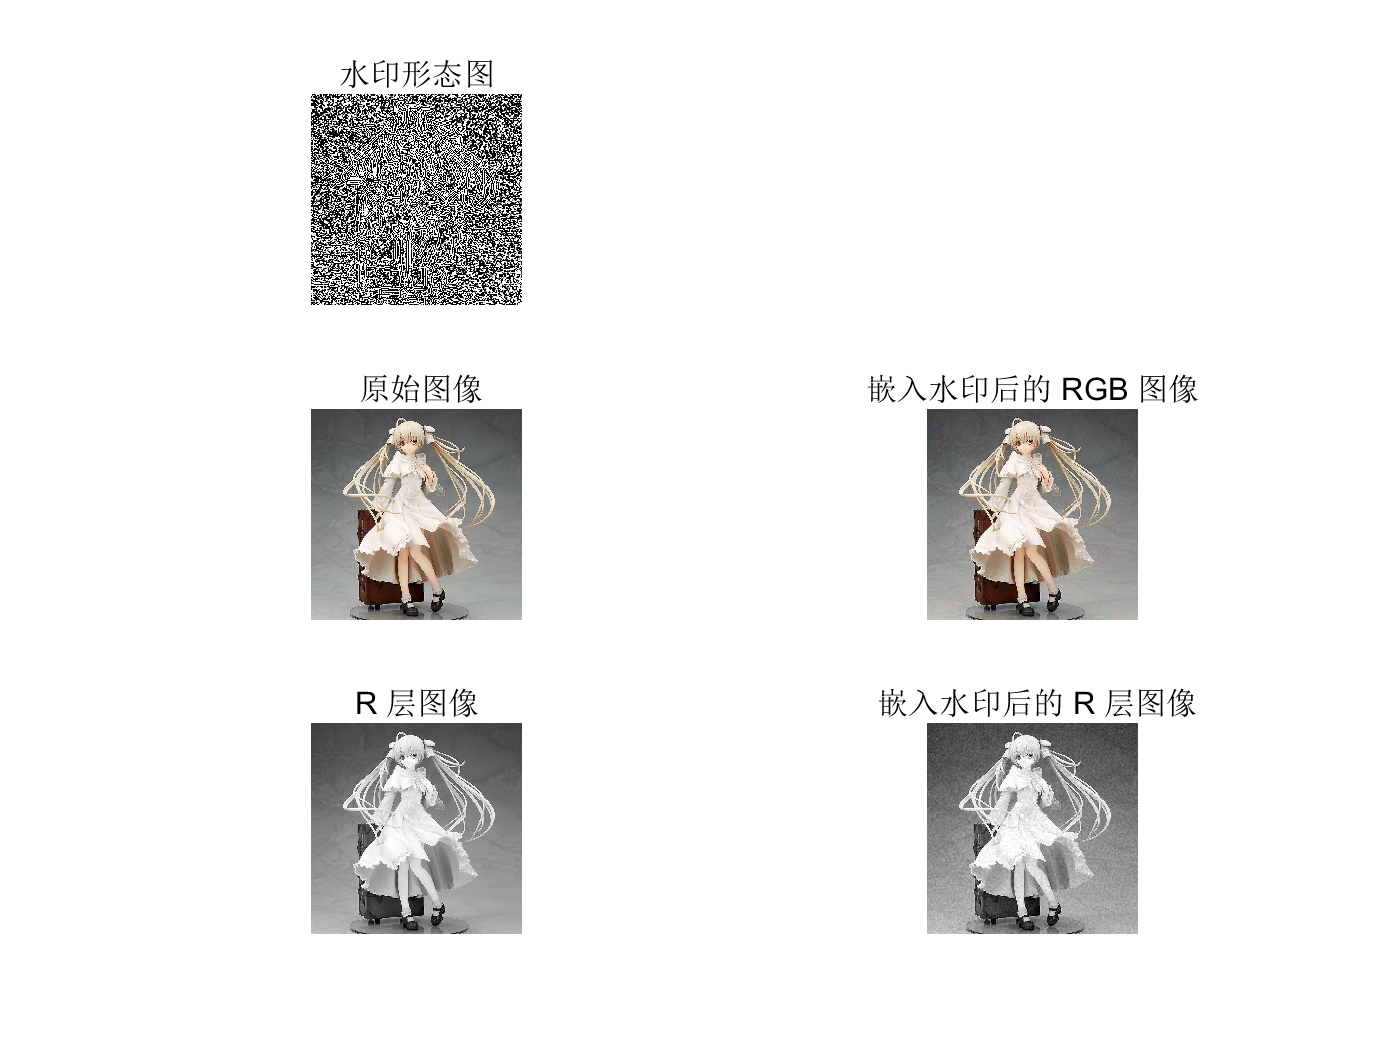

images = {'test_qm_JPEG_100.bmp', 'test_qm_JPEG_90.bmp', 'test_qm_JPEG_80.bmp', 'test_qm_JPEG_70.bmp', 'test_qm_JPEG_60.bmp', 'test_qm_JPEG_50.bmp', 'test_qm_JPEG_40.bmp', 'test_qm_JPEG_35.bmp', 'test_qm_JPEG_30.bmp', 'test_qm_JPEG_25.bmp', 'test_qm_JPEG_20.bmp', 'test_qm_JPEG_15.bmp'};
corr_Wcoef = zeros(12, 1) ;
corr_Dcoef = zeros(12, 1) ;
for i = 1 : 12
    [corr_coef, corr_DCTcoef] = wavedetect(string(images(i)), 'qm.jpg', 10, 'db6', 2, 0.5, 0.99);
    corr_Wcoef(i) = corr_coef;
    corr_Dcoef(i) = corr_DCTcoef;
end

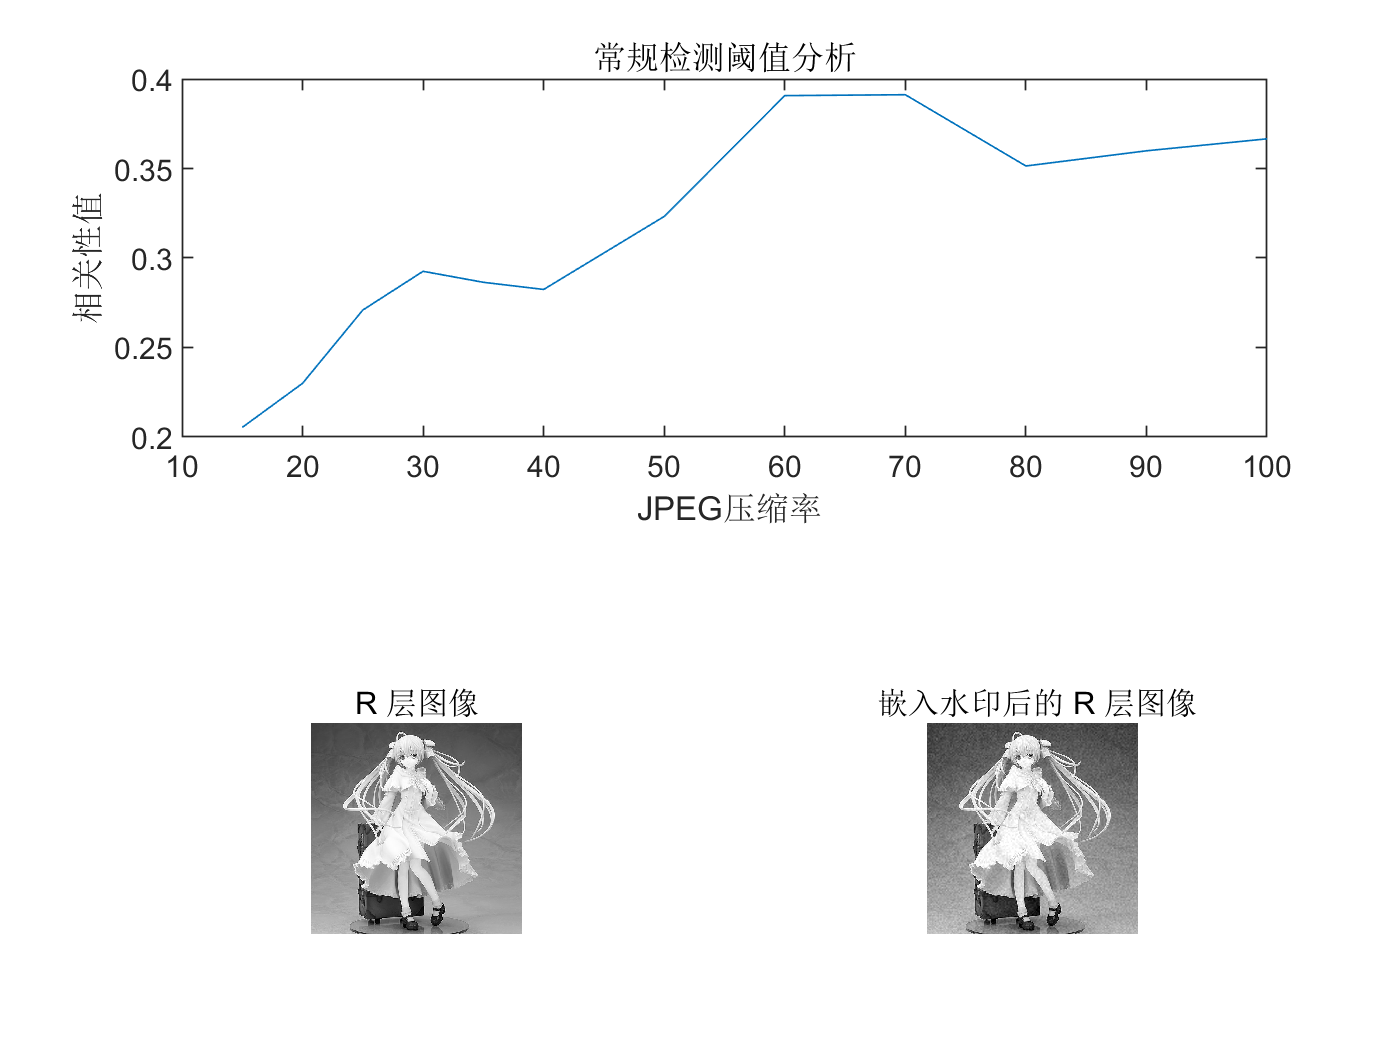


subplot( 211) ; 
plot([100, 90, 80, 70, 60, 50, 40, 35, 30, 25, 20, 15], abs( corr_Wcoef) ) ; 
title( '常规检测阈值分析' ) ; 
xlabel( ' JPEG压缩率' ) ; 
ylabel( '相关性值' ) ; 

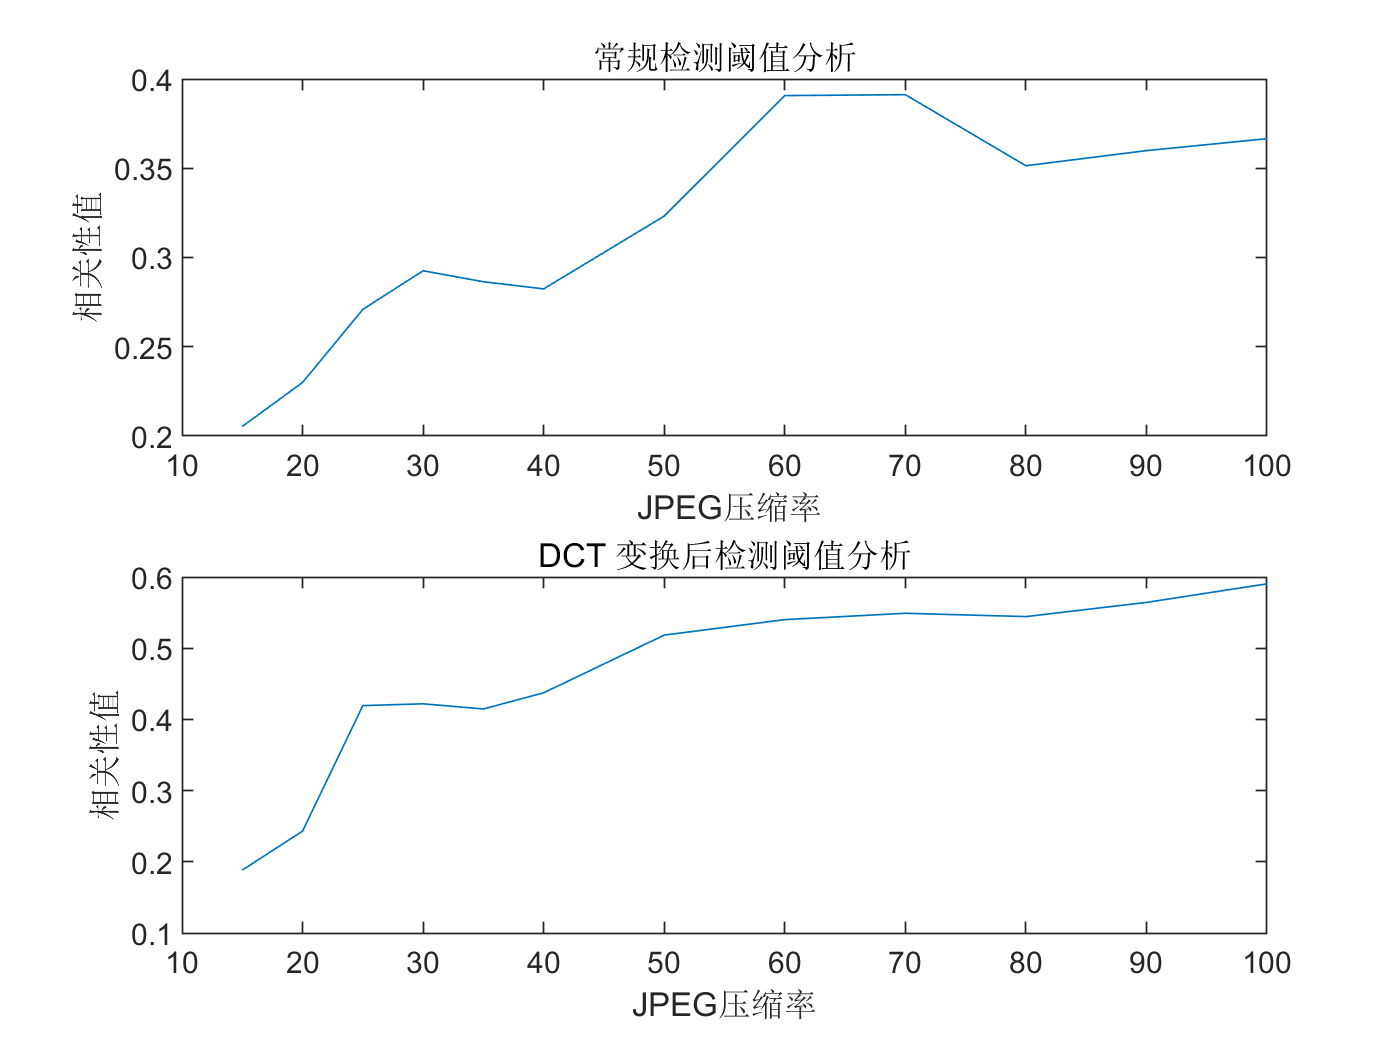

subplot( 212) ; plot([100, 90, 80, 70, 60, 50, 40, 35, 30, 25, 20, 15], abs( corr_Dcoef) ) ; 
%待测 
title( 'DCT 变换后检测阈值分析' ) ; 
xlabel( 'JPEG压缩率' ) ;
ylabel( '相关性值' ) ;